# Batch processing of Van der Pol Oscillator demo

Close any open pool of workers (if it is on the cluster, an open pool might cause your job the be queued instead of running)

delete(gcp('nocreate'));

Parallel pool using the 'GAB_2024b' profile is shutting down.


## Submit job locally

fprintf('Submitting batch job1... ');

Submitting batch job1... 


% batch(function, number of outputs, inputs, profile, pool size)
%job1 = batch('StiffODEparallel',4,{6}); 

job1 = batch('StiffODEparallel',4,{6},'Profile','Processes','Pool',3)


job1 = 

 Job

    Properties: 

                   ID: 2
                 Type: pool
             Username: garellan
                State: queued
         StorageBytes: 16888 (17 KB)
       SubmitDateTime: 24-Oct-2024 05:22:35
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [4 4]
           NumThreads: 1
          SpmdEnabled: true

      AutoAttachFiles: true
  Auto Attached Files: 

fprintf('Submitted Job 1!\n');

Submitted Job 1!


## Check status

We can check the status of the job by querying its state

job1.State

ans = 'finished'

% or wait for job to be completed
%wait(job1);

## Submit job to Cluster

nWorkers = 12;
fprintf('Submitting batch job using %i of workers... ', nWorkers);

Submitting batch job using 12 of workers... 


prof = 'GAB_2024b'; %Replace Name here!!

job2 = batch('StiffODEparallel', 4, {12},'Profile', prof,'Pool', nWorkers);  

fprintf('Submitted Job 2!\n');

Submitted Job 2!


## Plot data when job is finished

See the function definition for StiffODEparallel.m for the definition of the four output variables 

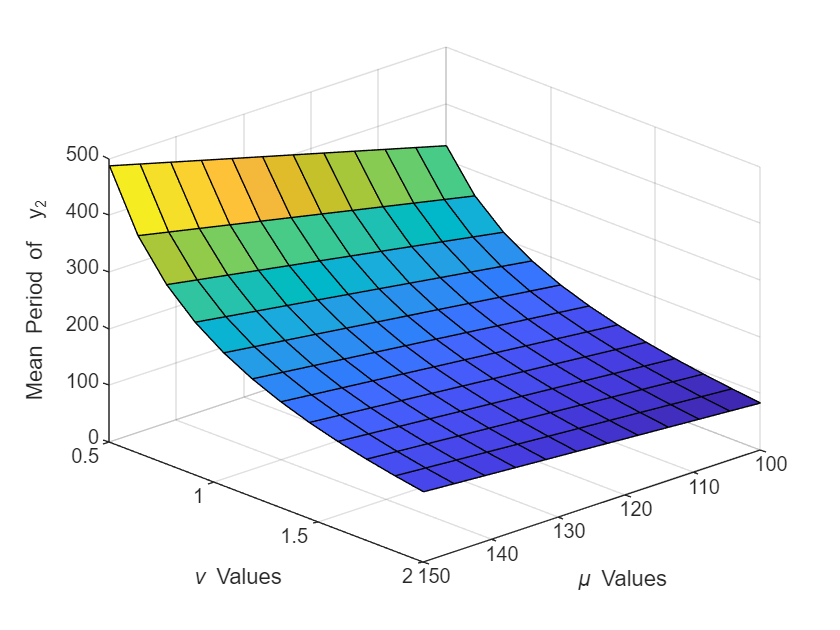

% Make sure job2 is finished and fetch results
wait(job2);  
jobOutput2=fetchOutputs(job2);

% Visualize results
visualizeStiffODE(jobOutput2);

fprintf('Computation time on a %i workers: %0.2f sec\n', nWorkers,jobOutput2{4});

Computation time on a 12 workers: 2.95 sec


## Compare Timings

Make sure job1 is finished and fetch results

wait(job1);
jobOutput1=fetchOutputs(job1);

fprintf('Computation time on 3 workers  : %0.2f sec\n', jobOutput1{4});

Computation time on 3 workers  : 3.48 sec


fprintf('Computation time on a %i workers: %0.2f sec\n', nWorkers,jobOutput2{4});

Computation time on a 12 workers: 2.95 sec


## Clean Up

These jobs are using physical resources. It's a best practice to delete them when done

delete(job1);
delete(job2);

*Copyright 2023The MathWorks, Inc.*